fun=@TTS_calculate_2;
options_1=optimoptions('fmincon','Algorithm','sqp');
options_2=optimoptions('fmincon','Algorithm','interior-point');
options_3=optimoptions('fminunc','HessUpdate','dfp');
options_4=optimoptions('simulannealbnd','FunctionTolerance',1,'PlotFcn','saplotbestf')

options_4 =   simulannealbnd options:

   Set properties:
         FunctionTolerance: 1
                   PlotFcn: 'saplotbestf'

   Default properties:
             AcceptanceFcn: @acceptancesa
              AnnealingFcn: @annealingfast
                  DataType: 'double'
                   Display: 'final'
                 HybridFcn: []
        InitialTemperature: 100
    MaxFunctionEvaluations: '3000*numberOfVariables'
             MaxIterations: Inf
        MaxStallIterations: '500*numberOfVariables'
                   MaxTime: Inf
            ObjectiveLimit: -Inf
                 OutputFcn: []
          ReannealInterval: 100
            TemperatureFcn: @temperatureexp


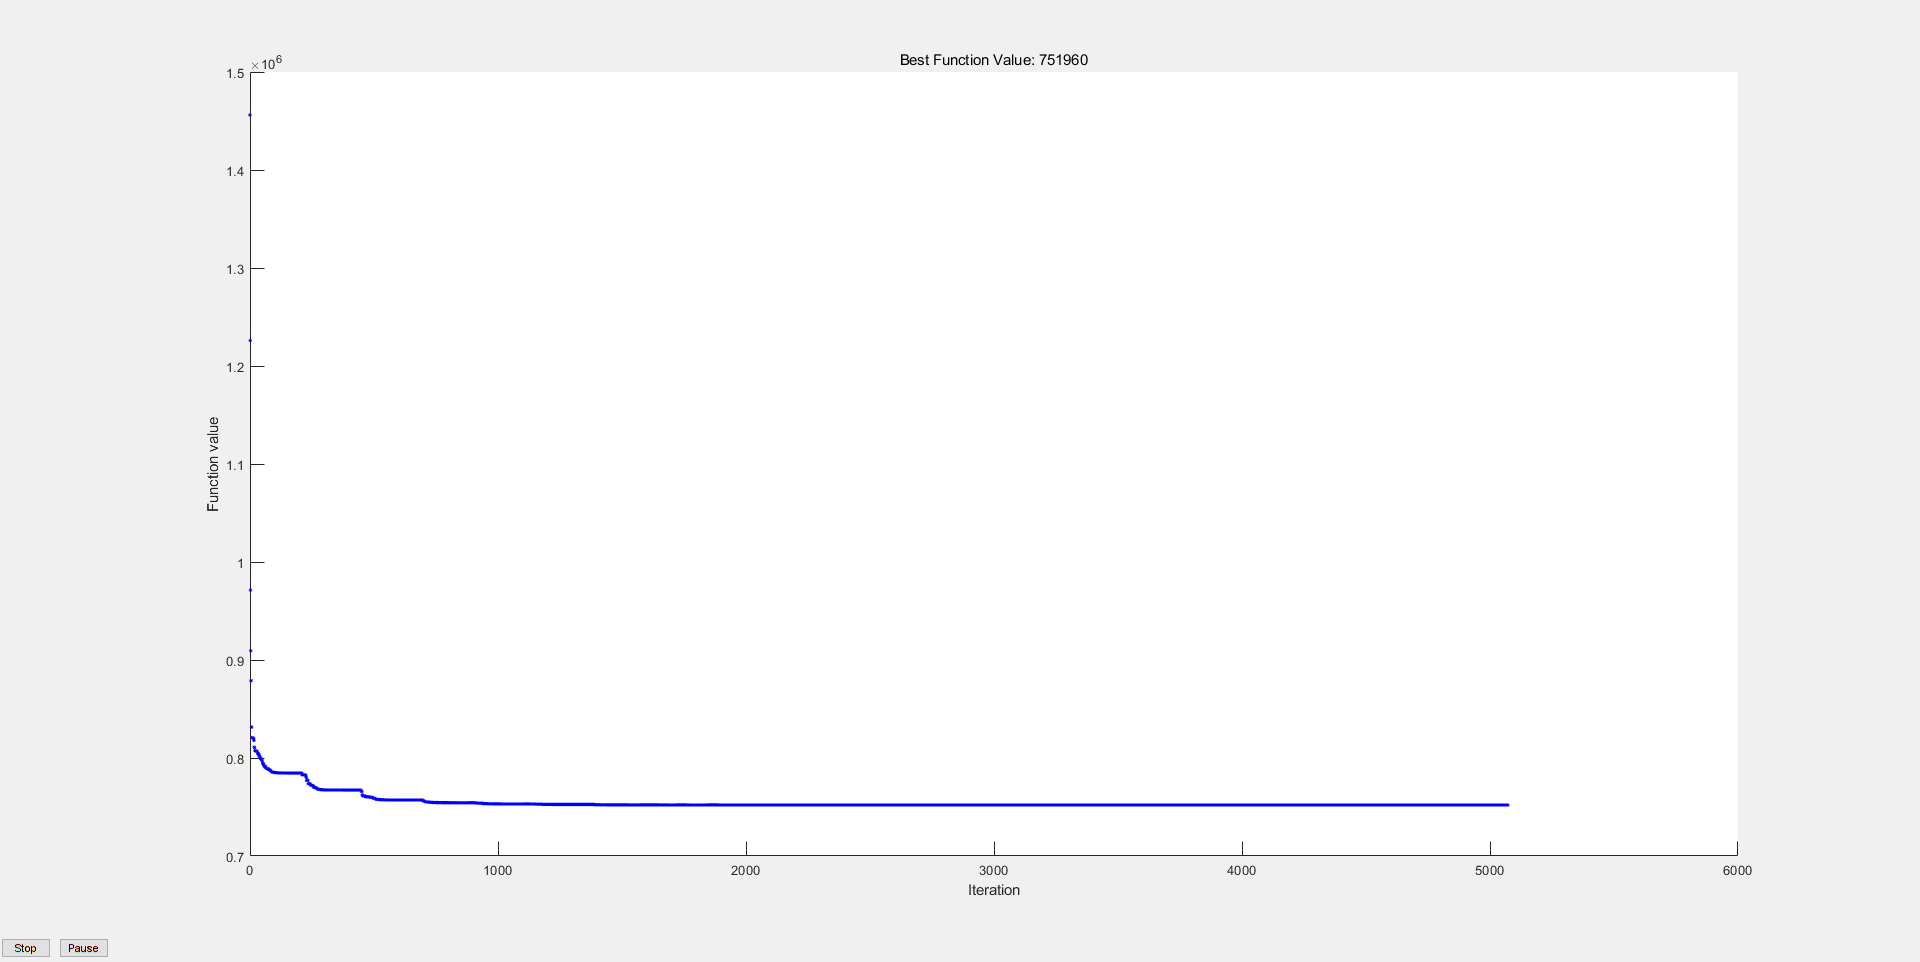

% [x1,fval_1]=fmincon(fun,15*ones(1,61),[],[],[],[],[],[],[],options_1)
% [x_2,fval_2]=fmincon(fun,45*ones(1,61),[],[],[],[],[],[],[],options_1)
% [x_3,fval_3]=fmincon(fun,15*ones(1,61),[],[],[],[],[],[],[],options_2)
% [x_4,fval_4]=fmincon(fun,45*ones(1,61),[],[],[],[],[],[],[],options_2)
% [x_5,fval_5]=fminunc(fun,15*ones(1,61),options_3)
% [x_6,fval_6]=fminunc(fun,45*ones(1,61),options_3)
[x_7,fval_7,exitflag,output]=simulannealbnd(fun,15*ones(1,61),15*ones(1,61),45*ones(1,61),options_4);

% [x_7,fval_7]=ga(fun,61,[],[],[],[],ones(1,61),7*ones(1,61),[],options)


% bar(x_8)

% subplot(2,3,1)
% bar(x_1)
% grid on;
% 
% subplot(2,3,2)
% bar(x_2)
% grid on;
% 
% subplot(2,3,3)
% bar(x_3)
% grid on;
% 
% subplot(2,3,4)
% bar(x_4)
% grid on;
% 
% subplot(2,3,5)
% bar(x_5)
% grid on;
% 
% subplot(2,3,6)
% bar(x_6)
% grid on;

% [TTS,y,x,z,m,s,u] = TTS_calculate_2(x_4)
% plot(x(1,:))

